EN3551: DIGITAL SIGNAL PROCESSING

Assignment 1: Detecting Harmonics in Noisy Data and Signal Interpolation using DFT

Index Number : 200377M

Task-01

Download the noise corrupted signal (xn test) of 1793 samples, that correspond to your

index number (Refer the Readme file in the signals folder to find your signal.). Each

signal contains 4 harmonics and severe white Gaussian noise. Consider the samples were

collected at a sampling rate of fs = 128 Hz over the period from 0 to 14 s. The four

harmonics are no greater than 64 Hz

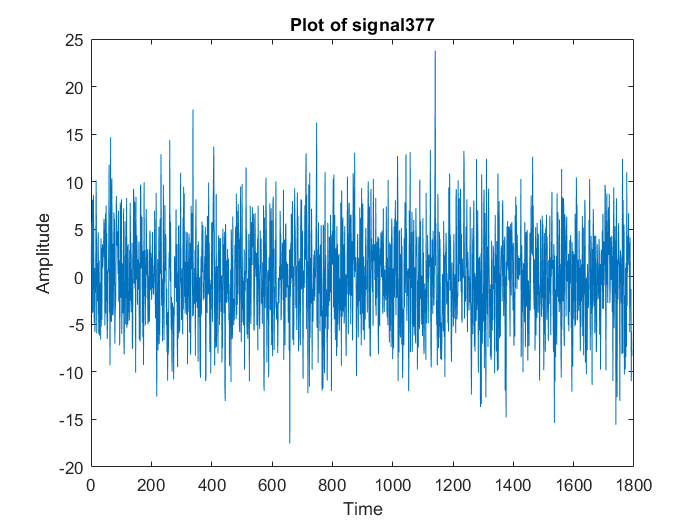

% Replace ABC with your specific index number digits
index_number = '377';

% Construct the signal variable name based on your index number
signal_variable_name = ['signal' index_number];

% Load the corresponding signal from the mat file
load([signal_variable_name '.mat'], 'xn_test');

% Plot the signal
plot(xn_test);

% Add labels and title for clarity
xlabel('Time');
ylabel('Amplitude');
title('Plot of signal377');

Construct several subsets by taking the first 128, 256, 512, 1024 and 1792 samples from

the sequence {x[n]} and denote them by S1, S2, S3, S4 and S5.

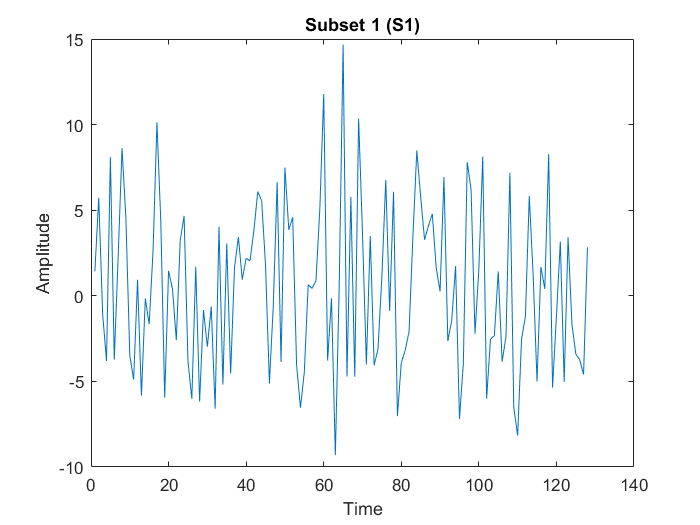


% Define the signal length and sampling rate
N = length(xn_test);  % 1793 samples
fs = 128;  % Hz

% Construct subsets
S1 = xn_test(1:128);
S2 = xn_test(1:256);
S3 = xn_test(1:512);
S4 = xn_test(1:1024);
S5 = xn_test(1:1792);

% Plot constructed subsets
plot(S1);
xlabel('Time');
ylabel('Amplitude');
title('Subset 1 (S1)');

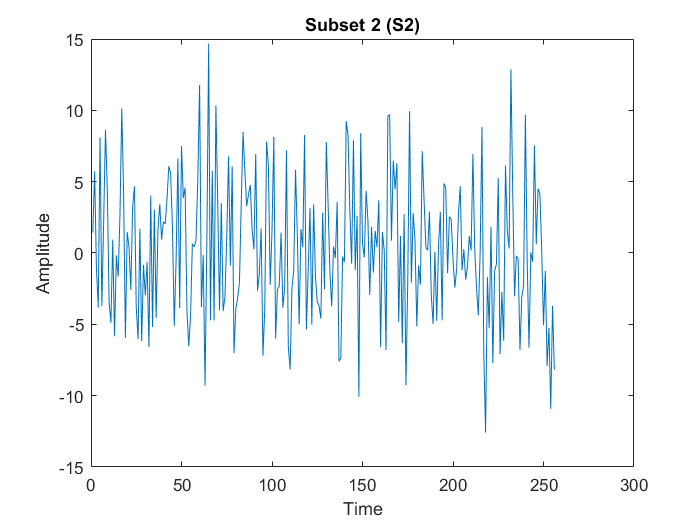


plot(S2);
xlabel('Time');
ylabel('Amplitude');
title('Subset 2 (S2)');

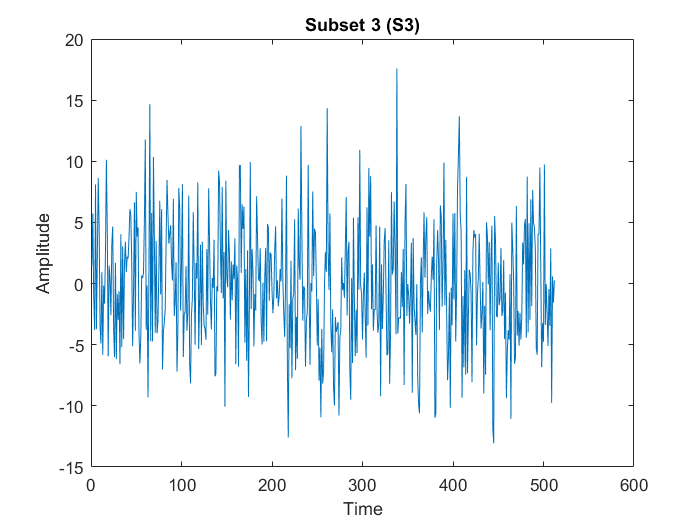


plot(S3);
xlabel('Time');
ylabel('Amplitude');
title('Subset 3 (S3)');

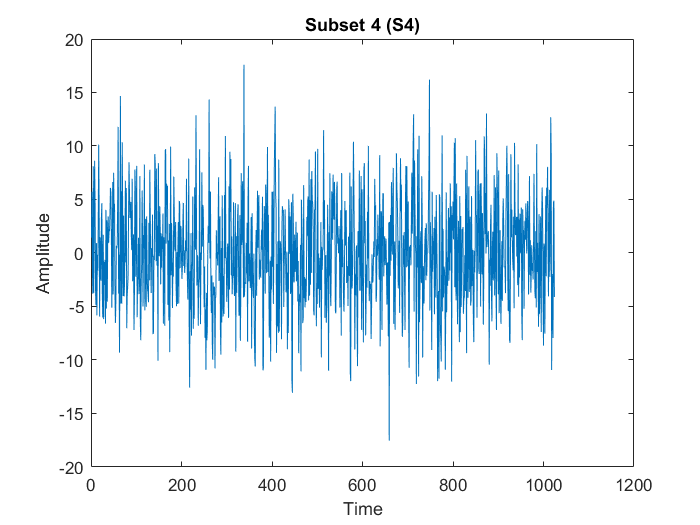


plot(S4);
xlabel('Time');
ylabel('Amplitude');
title('Subset 4 (S4)');

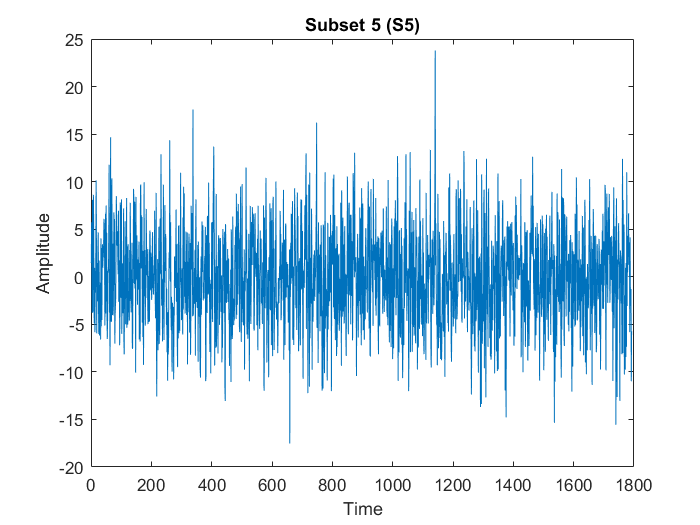


plot(S5);
xlabel('Time');
ylabel('Amplitude');
title('Subset 5 (S5)');

Construct several subsets by taking the first 128, 256, 512, 1024 and 1792 samples from

the sequence {x[n]} and denote them by S1, S2, S3, S4 and S5.

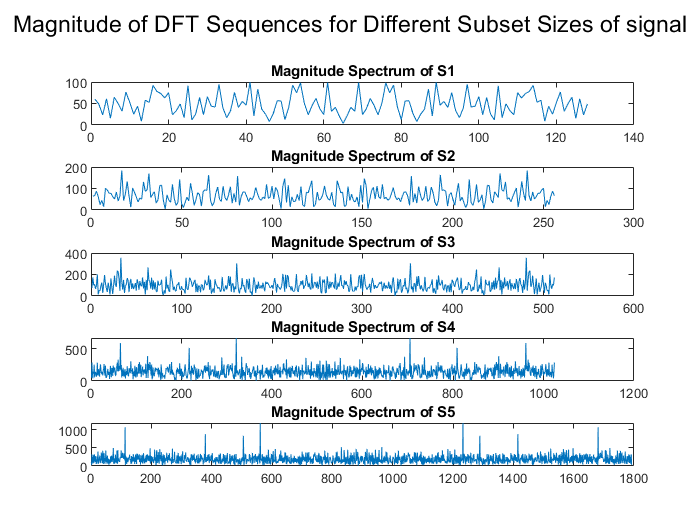

% Length of each subset
N1 = length(S1);
N2 = length(S2);
N3 = length(S3);
N4 = length(S4);
N5 = length(S5);

% Compute DFT for each subset
DFT_S1 = fft(S1,N1);
DFT_S2 = fft(S2,N2);
DFT_S3 = fft(S3,N3);
DFT_S4 = fft(S4,N4);
DFT_S5 = fft(S5,N5);

% Compute the magnitude of DFT sequences
Mag_S1 = abs(DFT_S1);
Mag_S2 = abs(DFT_S2);
Mag_S3 = abs(DFT_S3);
Mag_S4 = abs(DFT_S4);
Mag_S5 = abs(DFT_S5);

% Plot the magnitude spectra for each subset
subplot(5, 1, 1); plot(Mag_S1); title('Magnitude Spectrum of S1');
subplot(5, 1, 2); plot(Mag_S2); title('Magnitude Spectrum of S2');
subplot(5, 1, 3); plot(Mag_S3); title('Magnitude Spectrum of S3');
subplot(5, 1, 4); plot(Mag_S4); title('Magnitude Spectrum of S4');
subplot(5, 1, 5); plot(Mag_S5); title('Magnitude Spectrum of S5');

% Customize the plot layout to enhance visualization
sgtitle('Magnitude of DFT Sequences for Different Subset Sizes of signal');

Now apply the DFT averaging method described in the Section 2 above, where the length

of each subset is taken to be K = 128, and the number of subsets is taken to be L = 14.

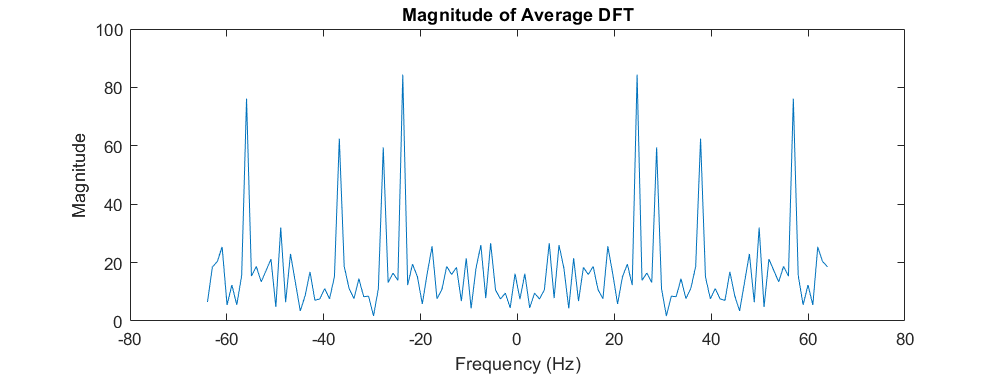

% Define parameters
K = 128;  % Number of samples in each subset
L = 14;   % Number of subsets
N = L * K; % Total number of samples

% Initialize an array to store the average DFT
Avg_DFT = zeros(1, K);

% Partition the signal and compute the DFT for each subset
for i = 1:L
    subset = xn_test((i - 1) * K + 1 : i * K);
    subset_DFT = fft(subset,K);
    Avg_DFT = Avg_DFT + subset_DFT;
end

% Calculate the average DFT by dividing by L
Avg_DFT = Avg_DFT / L;

% Create a frequency axis
frequencies = linspace(-fs/2, fs/2, K);

% Plot the magnitude of the average DFT
figure('Position', [100, 100, 800, 300]);
plot(frequencies,abs(Avg_DFT));
title('Magnitude of Average DFT');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Find peaks in the magnitude plot of the mean DFT
[~, peak_indices] = findpeaks(abs(Avg_DFT), 'MinPeakHeight', 40);  % Adjust the threshold as needed

% Convert peak indices to corresponding frequencies
peak_frequencies = frequencies(peak_indices);

% Display the frequencies corresponding to the detected peaks
disp('Frequencies corresponding to the detected peaks:');

Frequencies corresponding to the detected peaks:


disp(peak_frequencies);

  -55.9370  -36.7874  -27.7165  -23.6850   24.6929   28.7244   37.7953   56.9449



What is the smallest value of L such that the four peaks that correspond to the four

harmonics not greater than 64 remain clearly visible?

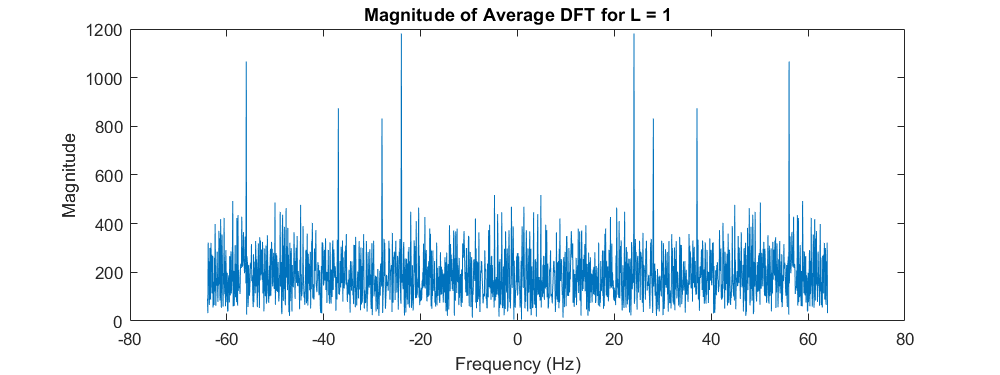

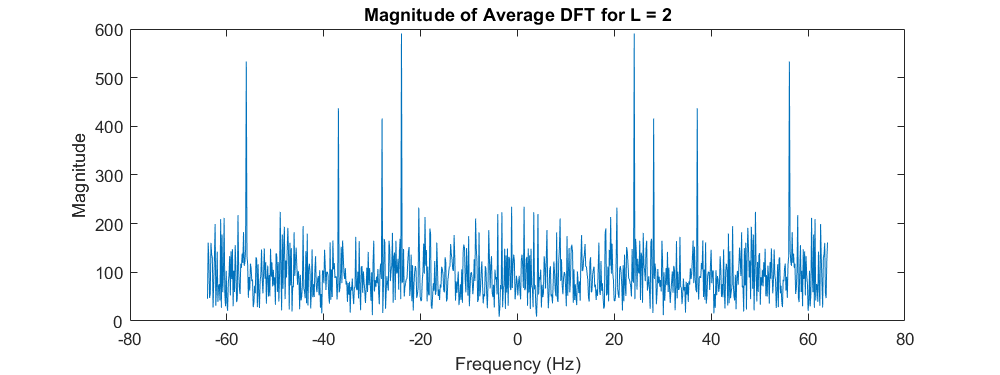

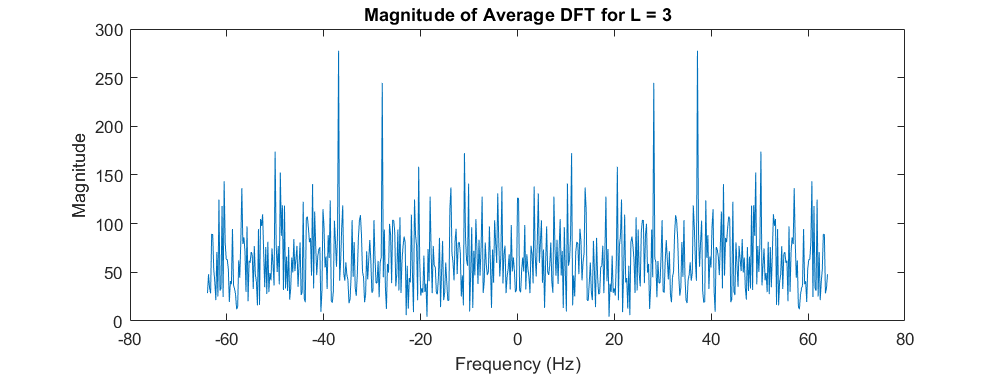

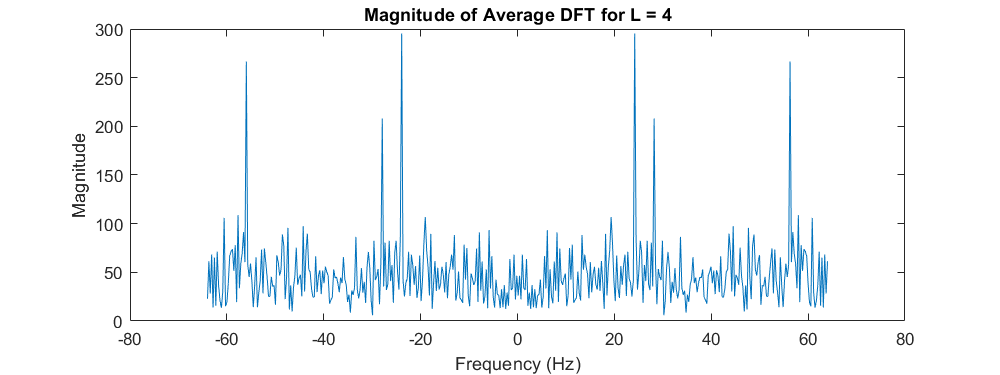

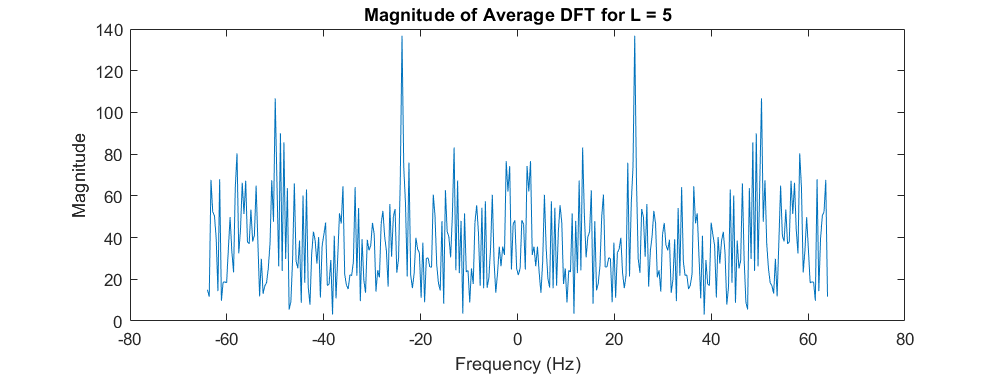

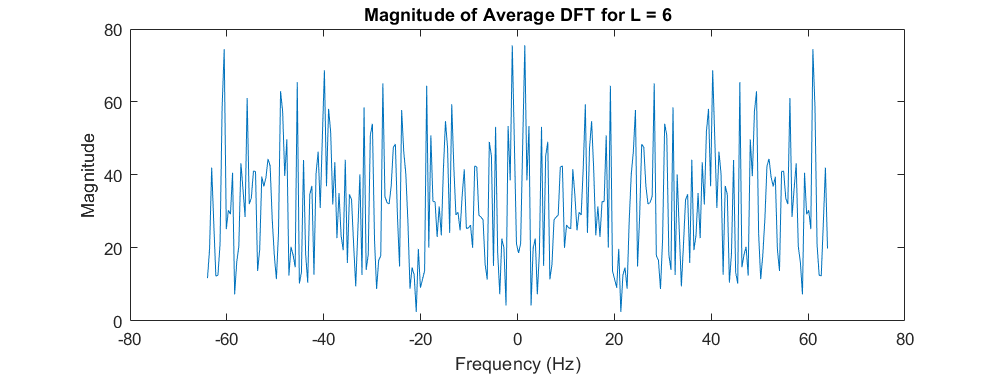

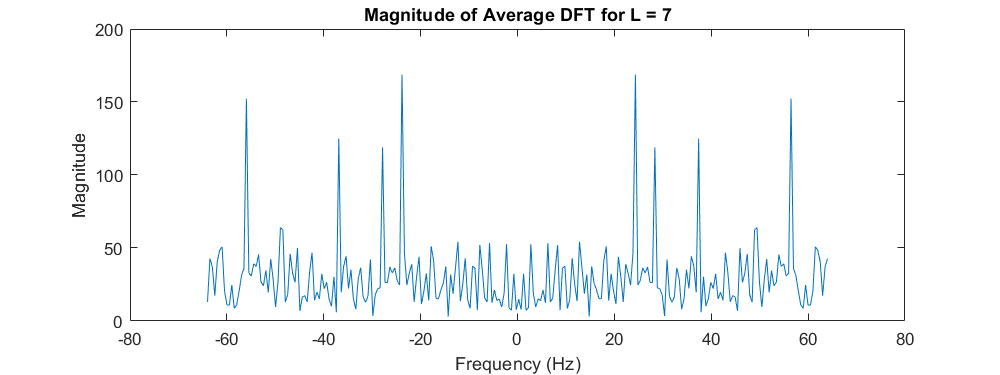

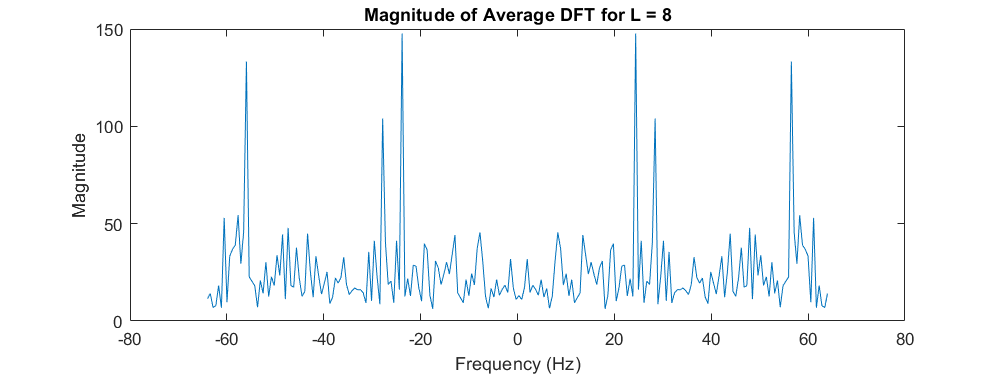

% Find the smallest value for L

% Define parameters
N = 1792; % Total number of samples
for L = 1:1:14 % Number of subsets
    K = floor(N/L);  % Number of samples in each subset
    
    % Initialize an array to store the average DFT
    Avg_DFT = zeros(1, K);
    
    % Partition the signal and compute the DFT for each subset
    for i = 1:L
        subset = xn_test((i - 1) * K + 1 : i * K);
        subset_DFT = fft(subset,K);
        Avg_DFT = Avg_DFT + subset_DFT;
    end
    
    % Calculate the average DFT by dividing by L
    Avg_DFT = Avg_DFT / L;
    
    % Create a frequency axis
    frequencies = linspace(-fs/2, fs/2, K);
    
    % Plot the magnitude of the average DFT
    figure('Position', [100, 100, 800, 300]);
    plot(frequencies,abs(Avg_DFT));
    title(['Magnitude of Average DFT for L = ', num2str(L)]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
end

To find peak , use stem plot

EN3551: DIGITAL SIGNAL PROCESSING

Assignment 1: Detecting Harmonics in Noisy Data and Signal Interpolation using DFT

Index Number : 200377M

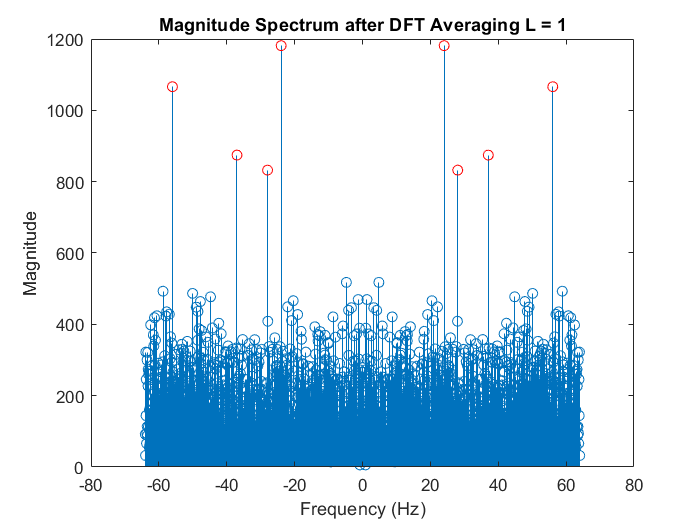

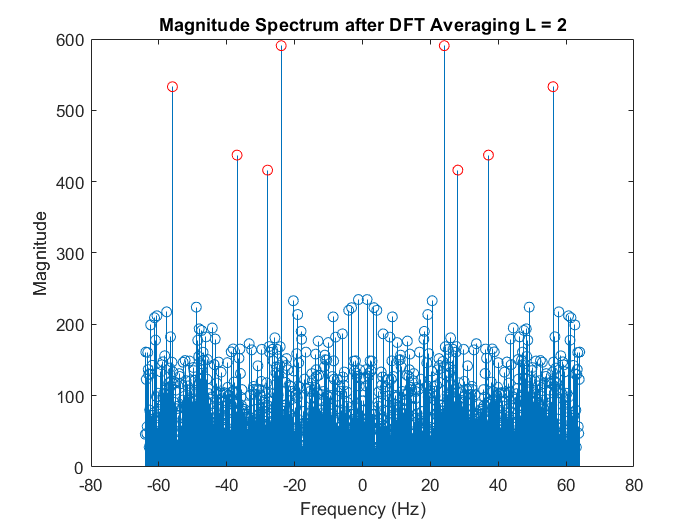

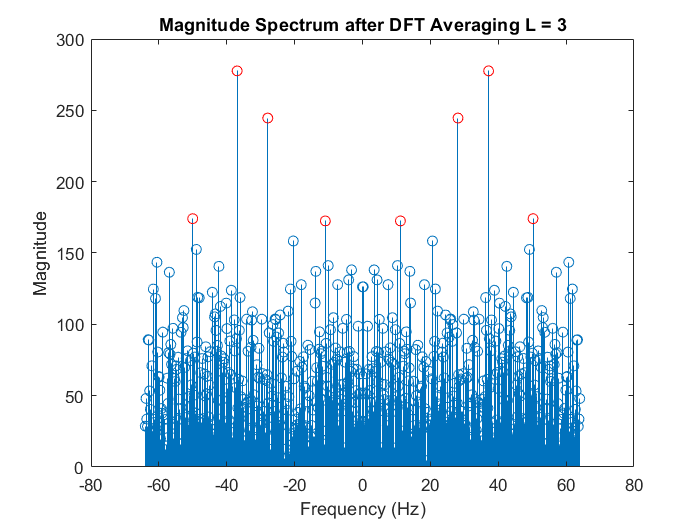

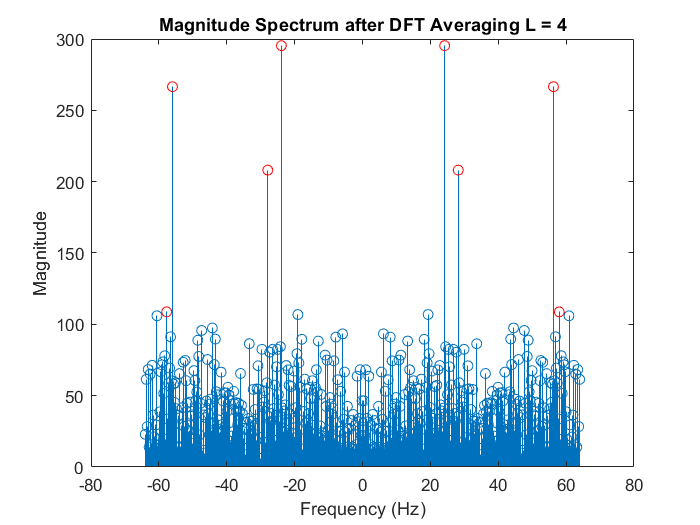

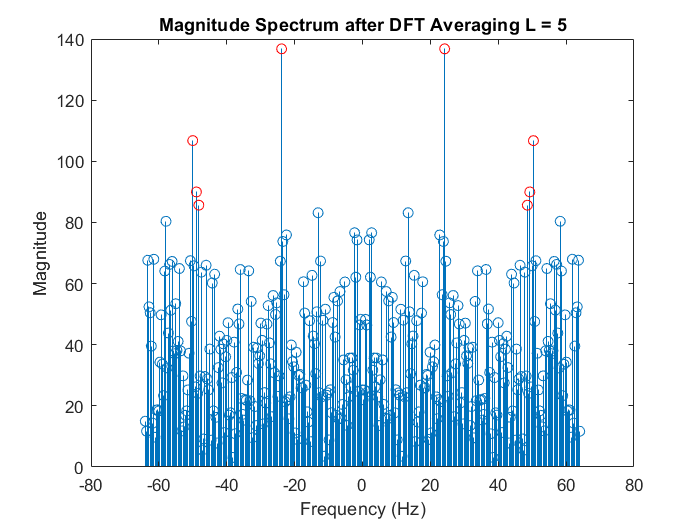

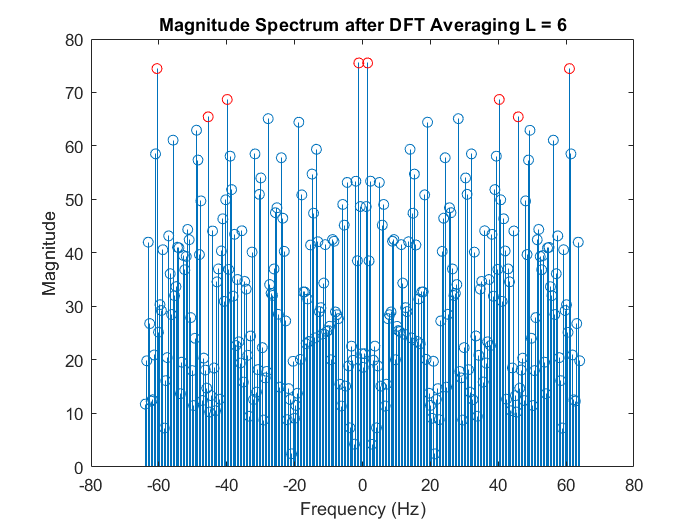

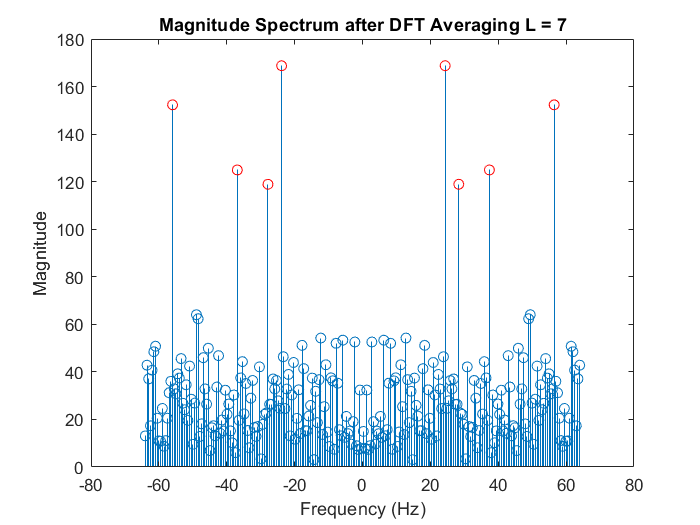

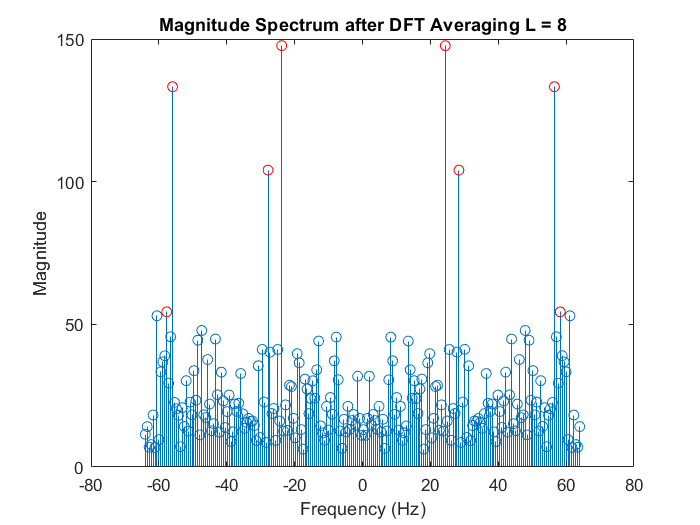

% Find the smallest value for L

% Define parameters
N = 1792; % Total number of samples
for L = 1:1:14 % Number of subsets
    K = floor(N/L);  % Number of samples in each subset
    
    % Initialize an array to store the average DFT
    Avg_DFT = zeros(1, K);
    
    % Partition the signal and compute the DFT for each subset
    for i = 1:L
        subset = xn_test((i - 1) * K + 1 : i * K);
        subset_DFT = fft(subset,K);
        Avg_DFT = Avg_DFT + subset_DFT;
    end
    
    % Calculate the average DFT by dividing by L
    Avg_DFT = Avg_DFT / L;
    
    % Create a frequency axis
    frequencies = linspace(-fs/2, fs/2, K);
    % Find the 8 highest peaks
    [~, sorted_indices] = sort(abs(Avg_DFT), 'descend');
    highest_peak_indices = sorted_indices(1:8);
    
    % Display the results
    figure;
    stem(frequencies, abs(Avg_DFT));
    title(['Magnitude Spectrum after DFT Averaging L = ' num2str(L)]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    hold on;
    plot(frequencies(highest_peak_indices), abs(Avg_DFT(highest_peak_indices)), 'ro');
end

Can one use other values for K (say K = 100 or K = 135)?. Explain why

We can use other values for K (e.g., K = 100 or K = 135) depending on our requirements. However, we need to keep in mind that the choice of K affects the frequency resolution of the DFT. Smaller K values provide better time resolution but poorer frequency resolution, and vice versa for larger K values. The choice of K depends on the trade-off we want between time and frequency resolution and the specific characteristics of our signal.

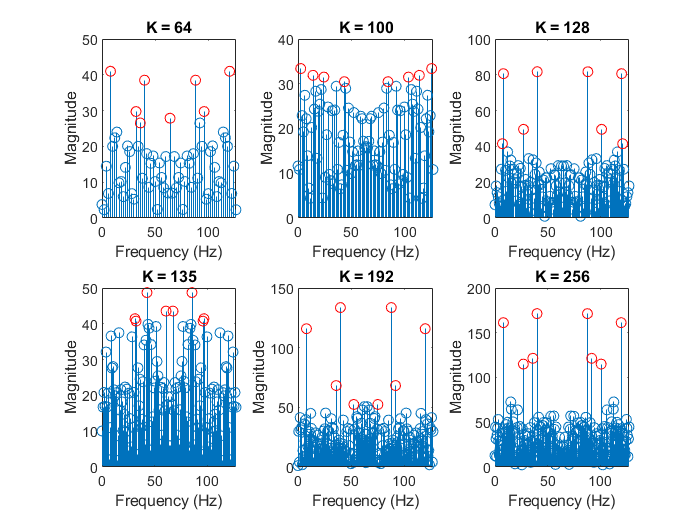

% Define values of K for the subplots
K_values = [64, 100, 128, 135, 192, 256];

% Create a figure with 6 subplots
figure;

for i = 1:length(K_values)
    K = K_values(i);
    
    % Initialize an array to store the average DFT
    Avg_DFT = zeros(1, K);
    
    % Partition the signal and compute the DFT for each subset
    for j = 1:length(K_values)
        subset = xn_test((j - 1) * K + 1 : j * K);
        subset_DFT = fft(subset, K);
        Avg_DFT = Avg_DFT + subset_DFT;
    end

    % Calculate the average DFT by dividing by the number of K_values
    Avg_DFT = Avg_DFT / length(K_values);

    % Create a frequency axis
    frequencies = (0:K-1) * (fs/K);
    
    % Find the 8 highest peaks in the magnitude of the average DFT
    [~, sorted_indices] = sort(abs(Avg_DFT), 'descend');
    highest_peak_indices = sorted_indices(1:8);
    
    % Create subplots
    subplot(2, 3, i);
    stem(frequencies, abs(Avg_DFT));
    title(['K = ' num2str(K)]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    hold on;
    plot(frequencies(highest_peak_indices), abs(Avg_DFT(highest_peak_indices)), 'ro');
end